# Homework 7

## [✔] Problem 14.42

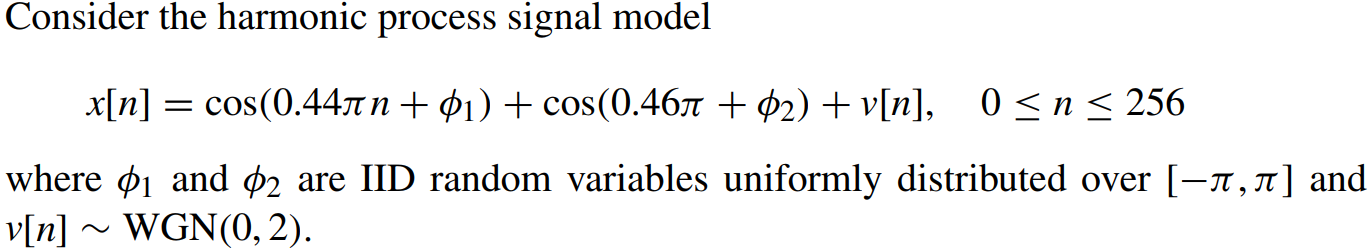

The autocorrelation of real sinusoid $z\left(n\right)=A\;\cos \left(\omega_0 n+\phi \right)$ is $r_{\mathrm{zz}} \left(\ell \right)=\frac{A^2 }{2}\cos \left(\omega_0 \ell \right)$. 

Since the PSD is the Fourier transform of the autocorrelation, we get:

        
$$S_{\mathrm{zz}} \left(\omega \right)=\frac{A^2 }{4}\delta \left(\omega +\omega_0 \right)+\frac{A^2 }{4}\delta \left(\omega -\omega_0 \right)$$


This means that power is concentrated at $\pm \omega_0$. In the PSD, we will therefore see two peaks ${\pm \omega }_0$ 

The autocorrelation of white Gaussian noise is $r_{\mathrm{vv}} \left(\ell \right)=\sigma_v^2 \delta \left(\ell \right)=2\delta \left(\ell \right)$. The PSD of Gaussian noise is constant around $\sigma_v^2$.

So the true PSD should be something like:


$$S_{\mathrm{xx}} \left(\omega \right)=\frac{1}{4}\delta \left(\omega -0\ldotp 44\pi \right)+\frac{1}{4}\delta \left(\omega -0\ldotp 46\pi \right)+2$$


### 1) Estimate the PSD using the periodogram and plot the spectrum.

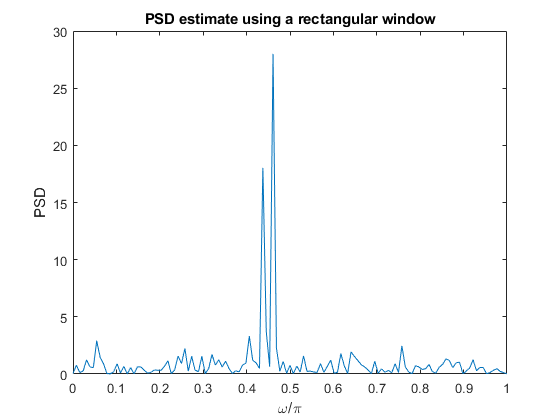


N = 256;
n = 0:N-1;
v = randn(1,N) * sqrt(2);
phi = 2*pi*(rand(1,2)-0.5);
x = cos(0.44*pi*n + phi(1)) + cos(0.46*pi*n + phi(2)) + v;
%plot(n, x); xlim([0, N]);

[I, w] = periodogram(x, [], N);
IdB = pow2db(I);
plot(w/pi, I);
xlabel('\omega/\pi')
ylabel('PSD')
title('PSD estimate using a rectangular window')

### 2) Estimate the PSD using the modified periodogram with Bartlett window  

Estimate the PSD using the modified periodogram with Bartlett window and plot the spectrum.  

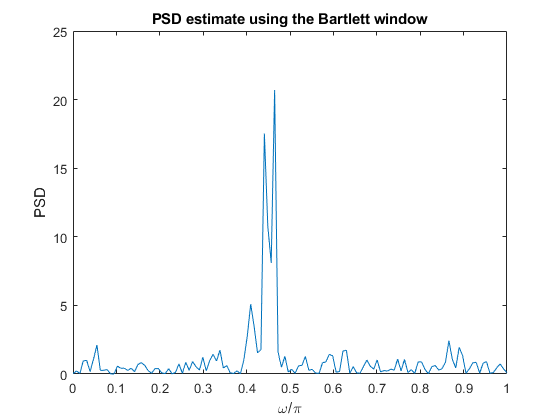

L = N;
I = periodogram(x, bartlett(L));
w = linspace(0,1,N/2)*pi;
plot(w/pi, I(1:N/2));
xlabel('\omega/\pi')
ylabel('PSD')
title('PSD estimate using the Bartlett window')

### 3) Estimate the PSD using the Blackman–Tukey method

Estimate the PSD using the Blackman–Tukey method with Parzen window and *L*=32 and plot the spectrum.

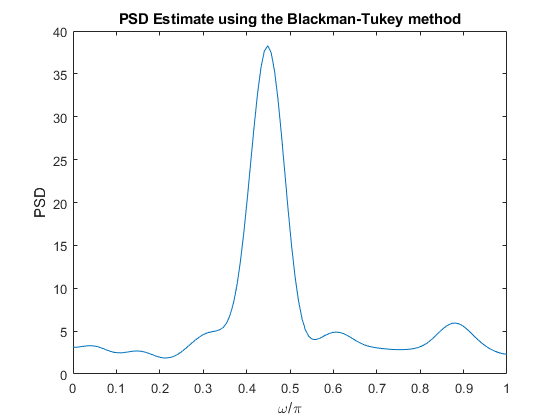

L = 32;
K = N;
I = psdbt(x,L,K);
plot(w/pi, I(1:N/2));
xlabel('\omega/\pi')
ylabel('PSD')
title('PSD Estimate using the Blackman-Tukey method')

### 4) Which method performs best in terms of signal resolution?

The PSD estimate using the periodogram (with rectangular window) shows two distinct peaks at the appropriate frequencies. However, the picture is not clear because there are some noise on the other frequencies. Using the Bartlett (triangular) window yields similar characteristics.

Blackman-Tukey smoothes out the noise but does not remove them completely. In addition, the BT method **smears out **the two frequency peaks into one peak.

In terms of signal resolution, it seems the window-based periodograms perform better.

## [✔] Problem 14.57

This problem uses the signal file f16.mat that contains noise recorded at the copilot’s seat of an F-16 airplane using a 16 bit A/D converter with $F_S =19\ldotp 98$ kHz. 

  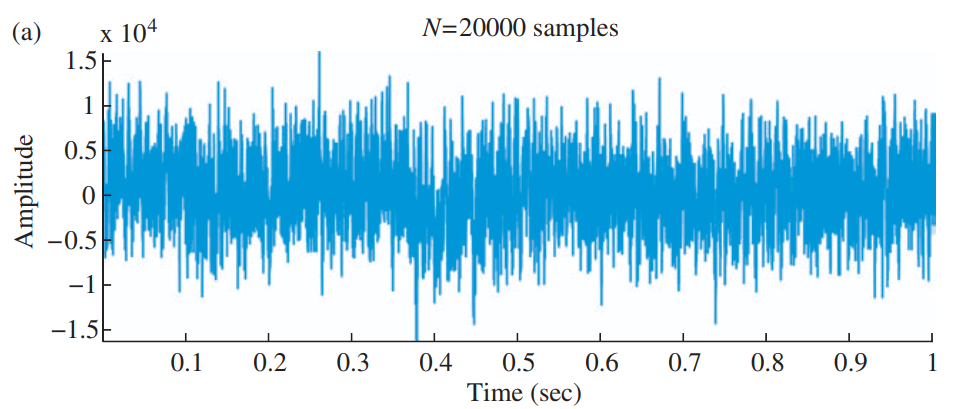

Figure (a) shows a waveform of F-16 noise recorded at the co-pilot’s seat with a sampling rate of 19.98 kHz using a 16 bit ADC.  

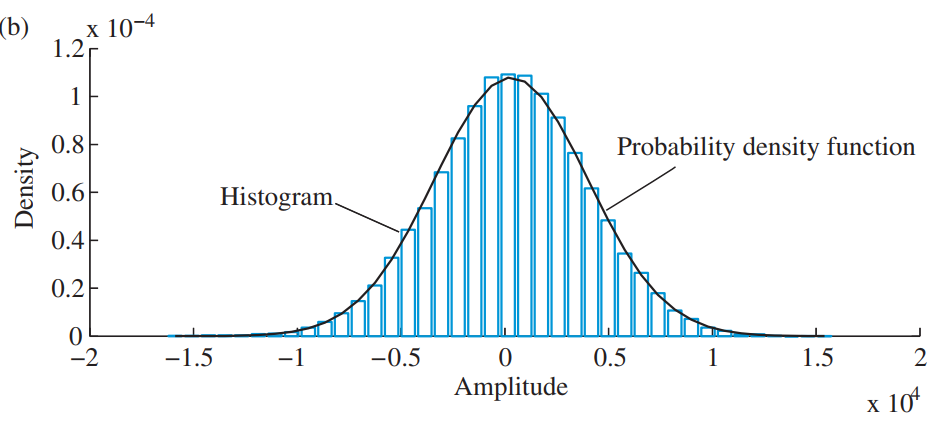

Figure (b) shows the histogram and theoretical probability density function of the F-16 noise.

We want to analyze this signal in terms of its ACRS and its spectral characteristics.  

### 1) Compute and plot the ACRS estimate of the noise process.

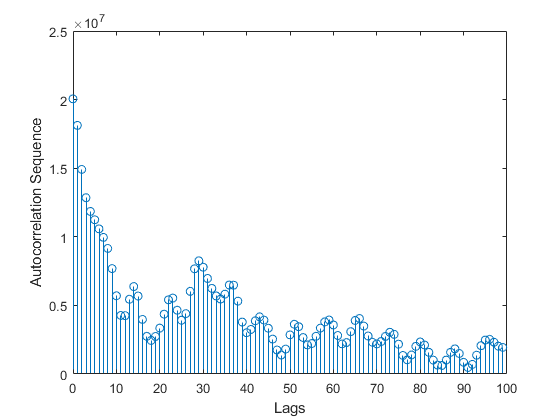

load('f16.mat')
y = f16;
L = 100;
r_yy = acrsfft(y, L); % MATLAB function from the book
stem(0:L-1, r_yy)
xlabel('Lags')
ylabel('Autocorrelation Sequence')

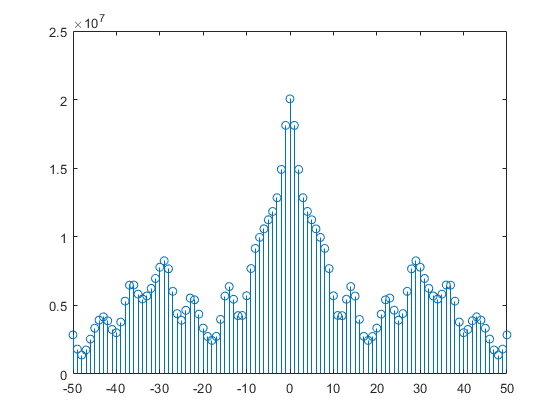

% Let us verify it with MATLAB's xcorr function 
[lags, r_yy] = xcorr(y, 50, 'biased');
stem(r_yy, lags)

### 2) Estimate model parameters for an *AR**(2) and AR(4) *models.

An AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model using the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ computed numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

An AR(2) model is given by:

        
$$y\left(n\right)=-\left(a_1 \;y\left(n-1\right)+a_2 \;y\left(n-2\right)\right)+b_0 x\left(n\right)$$


We can estimate the model parameters of a second-order AR model$p=2$ by creating two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form using the Toeplitz matrix:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

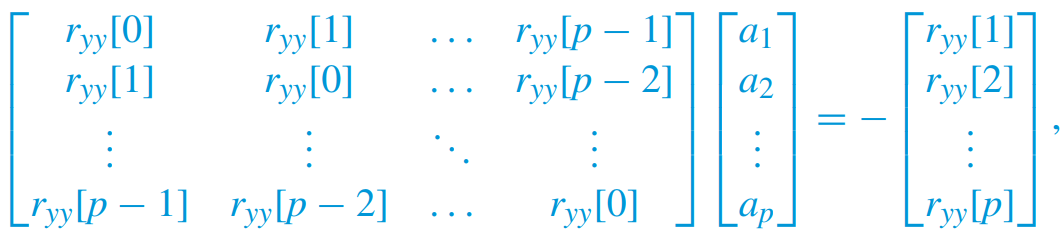

More compactly written as:

        
$${\mathit{\mathbf{R}}}_y \;\mathit{\mathbf{a}}=-{\mathit{\mathbf{r}}}_y$$


This is systems of linear equations which can be solved in MATLAB.

p = 2; % Model order
[r_yy, lags] = xcorr(y, p, 'biased');

% Select elements r_yy[0] to r_yy[p-1]
R_elems = r_yy(p+1:2*p);

% Create the Toeplitz matrix
R = toeplitz(R_elems);

% Select elements r_yy[1] to r_yy[p]
r = r_yy(p+2:2*p+1);

% Solve systems of linear equations using mldivide function
a = mldivide(R, -r)

a =    -1.2628
    0.3975


Once we have found the coefficients, we can predict the signal using the previous two samples:

        
$$y\left(n\right)=-\left(-1\ldotp 2628\;y\left(n-1\right)+0\ldotp 3975y\left(n-2\right)\right)+b_0 x\left(n\right)$$


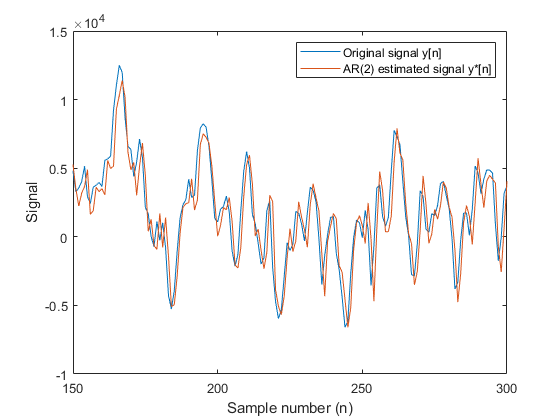

N = 1000;
y_hat = zeros(N);
n = 3:N; % Trick to make it work in MATLAB
y_hat(n) = -(a(1)*y(n-1) + a(2)*y(n-2));

% Plotting code
n = 1:N;
plot(n, y(n), n, y_hat(n))
legend('Original signal y[n]', 'AR(2) estimated signal y*[n]');
xlabel('Sample number (n)')
ylabel('Signal')
xlim([150, 300]) % Zoom 

[a, v] = arfit(y, 4)

a =    -1.4473
    0.9584
   -0.4942
    0.0705


v = 2.6038e+06

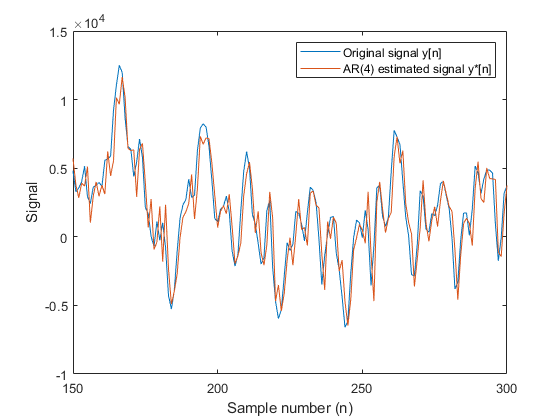


N = 1000;
y_hat = zeros(N);
n = 5:N; % Trick to make it work in MATLAB
y_hat(n) = -(a(1)*y(n-1) + a(2)*y(n-2) + a(3)*y(n-3) + a(4)*y(n-4));


% Plotting code
n = 1:N;
plot(n, y(n), n, y_hat(n))
legend('Original signal y[n]', 'AR(4) estimated signal y*[n]');
xlabel('Sample number (n)')
ylabel('Signal')
xlim([150, 300]) % Zoom 

### 3) Compute and plot the PSD estimate using the AR(2) and AR(4) models.  

The power spectrum of an ARMA(p, q) process is given by:

        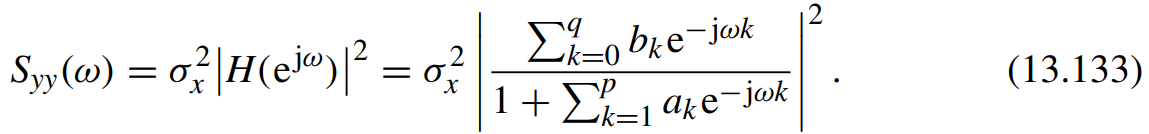

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


This is implemented in the function ar2psd():

N = 256;

[a2, v2] = arfit(y, 2);
[S2, w] = ar2psd(a2, v2, N);

[a4, v4] = arfit(y, 4);
[S4, w] = ar2psd(a4, v4, N);

[a10, v10] = arfit(y, 10);
[S10, w] = ar2psd(a10, v10, N);

w_over_pi = w/pi;
S2db = pow2db(S2); % Use real(S2) to get rid of warning
S4db = pow2db(S4);
S10db = pow2db(S10);

plot(w_over_pi, S2db, w_over_pi, S4db, w_over_pi, S10db)

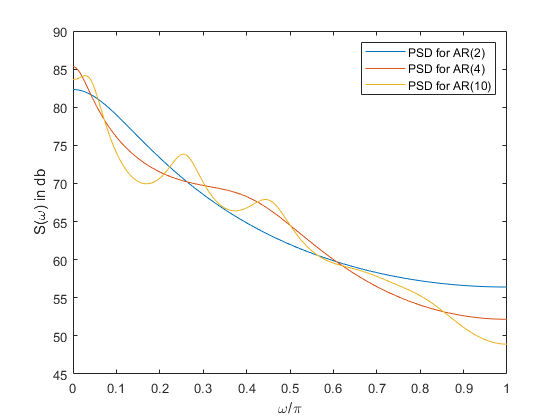

legend('PSD for AR(2)','PSD for AR(4)', 'PSD for AR(10)')
xlabel('\omega/\pi')
ylabel('S(\omega) in db')

### 4) Compute and plot the periodogram PSD estimate of the noise process.  

We can compute a PSD estimate using the periodogram() function in MATLAB:

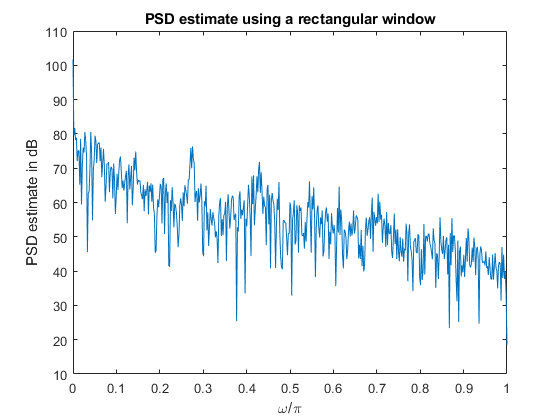

N = 1024;
[I, w] = periodogram(y, [], N);
IdB = pow2db(I);
plot(w/pi, IdB);
xlabel('\omega/\pi')
ylabel('PSD estimate in dB')
title('PSD estimate using a rectangular window')

### 👀 5) Compute the Bartlett PSD estimate

Compute the Bartlett PSD estimate using L = 32, 64, and 128. Plot your result of the averaged estimate.

**How do we compute the Bartlett PSD estimate? The periodogram() function in MATLAB complains**

N = 1024;
% This results in an error:
% "The WINDOW must be a vector of the same length as the signal"
% Can we just pad the window signal with zeros?
%[I_L32, w] = periodogram(y, bartlett(32), N);
%[I_L64, w] = periodogram(y, bartlett(64), N);
%[I_L128, w] = periodogram(y, bartlett(128), N);
%plot(w/pi, pow2db(I_L32));

### 6) Compute the Blackman–Tukey PSD estimate

Compute the Blackman-Tukey PSD estimate using *L *= 32, 64, and 128 using the Bartlett lag window. Plot your result of the averaged estimate.

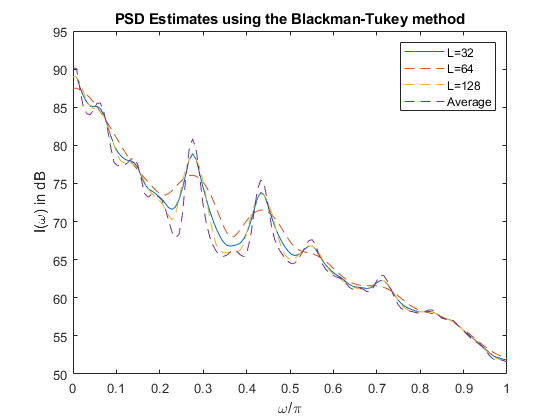

load('f16.mat'); y = f16;

N = 256;
w = linspace(0, 1, N/2);
I_L32 = psdbt(y, 32, N);
I_L64 = psdbt(y, 64, N);
I_L128 = psdbt(y, 128, N);

% Concatenate along the second dimension
I_con = cat(2, I_L32, I_L64, I_L128);

% Compute the mean along the second dimension
I_mean = mean(I_con, 2);

plot(w, pow2db(I_mean), w, pow2db(I_L32), '--', w, pow2db(I_L64), '--', w, pow2db(I_L128), '--');
legend('L=32', 'L=64', 'L=128', 'Average')
title('PSD Estimates using the Blackman-Tukey method')
xlabel('\omega/\pi')
ylabel('I(\omega) in dB')

### 7) Compute the Welch PSD estimate

Compute the Welch PSD estimate using 50% overlap, Hamming window, and *L *= 32, 64, and 128. Plot your result of the averaged estimate.  

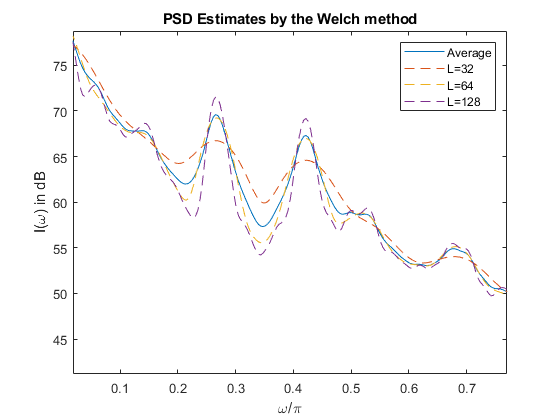

N = 256;
N_fft = 512;
overlap_pct = 0.5;
w = linspace(0, 1, N+1);

% Speed up computation by using a subset of the data
y_reduced = y(1:N*10);

I_L32 = pwelch(y_reduced, hamming(32), overlap_pct*32, N_fft);
I_L64 = pwelch(y_reduced, hamming(64), overlap_pct*64, N_fft);
I_L128 = pwelch(y_reduced, hamming(128), overlap_pct*128, N_fft);

% Concatenate along the second dimension
I_concat = cat(2, I_L32, I_L64, I_L128);

% Compute the mean along the second dimension
I_mean = mean(I_concat, 2);

plot(w, pow2db(I_mean), w, pow2db(I_L32), '--', w, pow2db(I_L64), '--', w, pow2db(I_L128), '--');

legend('Average', 'L=32', 'L=64', 'L=128')
title('PSD Estimates by the Welch method')
xlabel('\omega/\pi')
ylabel('I(\omega) in dB')

### 👀 8) Compare the plots in the above four parts and comment on your observation.  

## [✔] ADSI Problem 4.21: Minimum variance spectral estimation

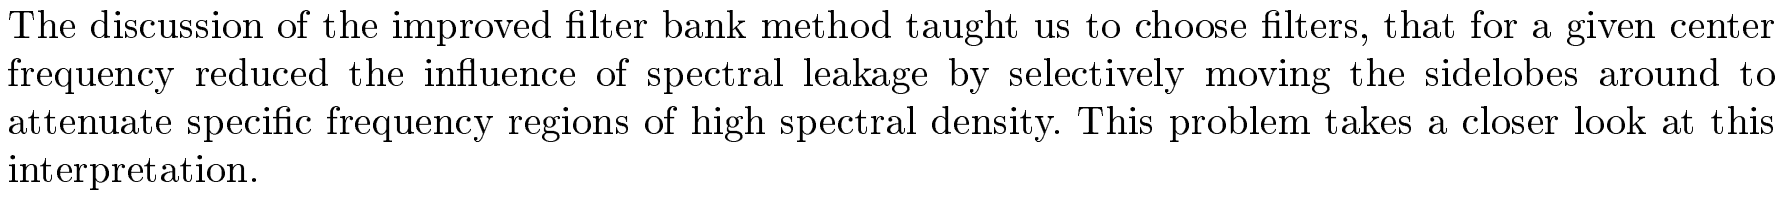

### 1) Create a stable signal model

Once we have created a signal, we can check whether it is stable by ensuring that all the poles and zeros are within the unit circle.

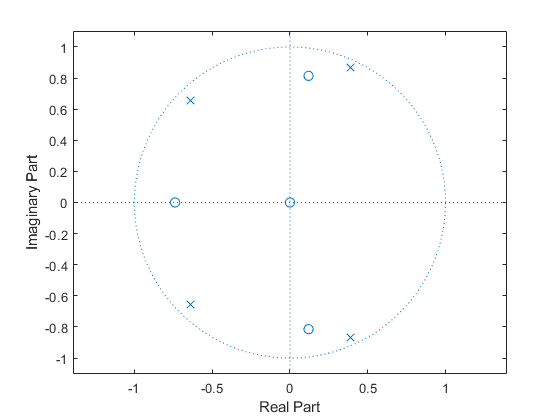

b = [2, 1, 1, 1];
a = [1, 0.5, 0.75, 0.5, 0.75];
zplane(b,a)

### 2) Use the signal model to plot the true spectrum.  

We can plot the true spectrum by plotting the magnitude response of the transfer function or simply use the freqz function in MATLAB:

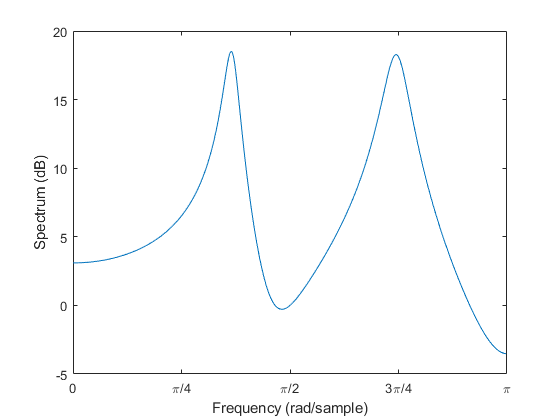

[H,w] = freqz(b, a);
plot(w, pow2db(H.*conj(H)));
set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Spectrum (dB)')
xlim([0, pi]);

### 3) Create a realization of the signal and determine the autocorrelation matrix ***R****x *in an appropriate size.

We can create a realisation of a signal using the filter function in MATLAB:

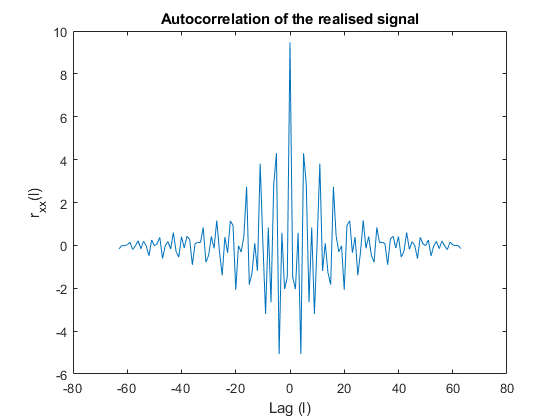

N = 4096;
n = randn(N,1);
x = filter(b, a, n);
N_Rx = 64; % size of autocorrelation matrix
[r_xx, lags] = xcorr(x, N_Rx-1, 'biased');

% Plot the autocorrelation for fun
plot(lags, r_xx);
xlabel('Lag (l)')
ylabel('r_{xx}(l)')
title('Autocorrelation of the realised signal')

% Create the autocorrelation matrix
R_xx = toeplitz(r_xx(N_Rx:end))

R_xx =     9.4710   -1.4924   -2.0381    0.5877   -5.0721    4.2947    2.8448   -2.6558    0.8335   -3.2026    0.1234    3.8139   -1.1893    0.1061   -1.2806   -1.8279    2.7342    0.4415   -0.3067   -0.0175   -2.0723    0.9343    1.1433   -0.3510    0.3914   -1.3921   -0.2973    1.1620   -0.1369    0.4178   -0.4638   -0.7818    0.8400    0.1280    0.1448    0.0847   -0.9084    0.2935    0.4241   -0.1217    0.4124   -0.5452   -0.2823    0.6002   -0.1792    0.1771   -0.0092   -0.6136    0.3753    0.0764
   -1.4924    9.4710   -1.4924   -2.0381    0.5877   -5.0721    4.2947    2.8448   -2.6558    0.8335   -3.2026    0.1234    3.8139   -1.1893    0.1061   -1.2806   -1.8279    2.7342    0.4415   -0.3067   -0.0175   -2.0723    0.9343    1.1433   -0.3510    0.3914   -1.3921   -0.2973    1.1620   -0.1369    0.4178   -0.4638   -0.7818    0.8400    0.1280    0.1448    0.0847   -0.9084    0.2935    0.4241   -0.1217    0.4124   -0.5452   -0.2823    0.6002   -0.1792    0.1771   -0.0092   -0.6136  

% Compute the inverse of the autocorrelation matrix
R_xx_inv = inv(R_xx)

R_xx_inv =     0.2597   -0.0064    0.0644   -0.0340    0.1791   -0.1091   -0.0168   -0.0170    0.0790   -0.0139   -0.0154   -0.0105    0.0305    0.0060   -0.0011   -0.0087    0.0069    0.0018    0.0012   -0.0126    0.0068    0.0046    0.0110   -0.0050    0.0072    0.0087    0.0049   -0.0008    0.0007    0.0028   -0.0054   -0.0078   -0.0054    0.0009   -0.0047    0.0008   -0.0020    0.0047   -0.0066    0.0020   -0.0080    0.0055   -0.0080    0.0007   -0.0044    0.0117   -0.0085    0.0088   -0.0042    0.0100
   -0.0064    0.2598   -0.0080    0.0653   -0.0383    0.1817   -0.1087   -0.0162   -0.0189    0.0793   -0.0135   -0.0152   -0.0112    0.0302    0.0062   -0.0011   -0.0088    0.0067    0.0020    0.0013   -0.0127    0.0067    0.0045    0.0110   -0.0050    0.0070    0.0087    0.0049   -0.0007    0.0006    0.0030   -0.0053   -0.0075   -0.0053    0.0011   -0.0048    0.0008   -0.0021    0.0048   -0.0068    0.0020   -0.0080    0.0055   -0.0081    0.0006   -0.0044    0.0119   -0.0088    0.00

### 4) Calculate the spectrum using Eq. (14.4.12) from the note.

We can compute minimum variance power spectrum estimate as follows

        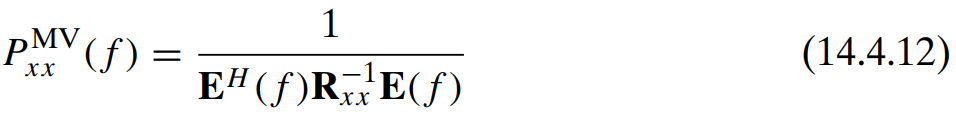

where

- $f$ is the frequency,

- ${\mathit{\mathbf{R}}}_{\mathrm{xx}}$ is the autocorrelation matrix

- $\mathit{\mathbf{E}}\left(f\right)$ is the constraint vector:

                    

This is implemented in the function psdmv() function (see at the end of the document):

M = 64; % Size of the autocorrelation matrix
kF = 4; % Frequency resolution multiplier
[I, w] = psdmv(x, M, kF);
[H,w2] = freqz(b, a, M*kF);
plot(w, pow2db(H.*conj(H)), w, pow2db(I));

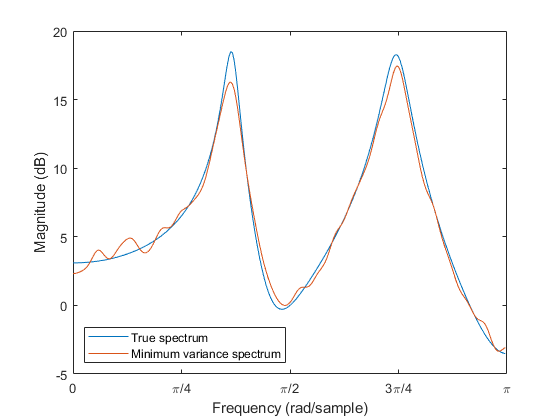

set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude (dB)')
legend({'True spectrum', 'Minimum variance spectrum'}, 'Location', 'southwest')

xlim([0, pi]);

### 5) Calculate the optimum filters

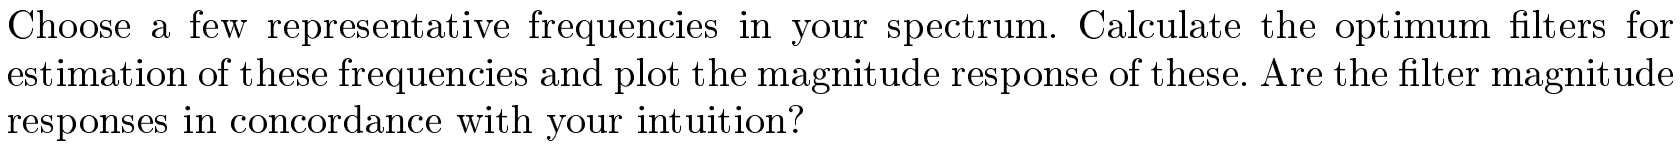

The optimum filters are given by

        

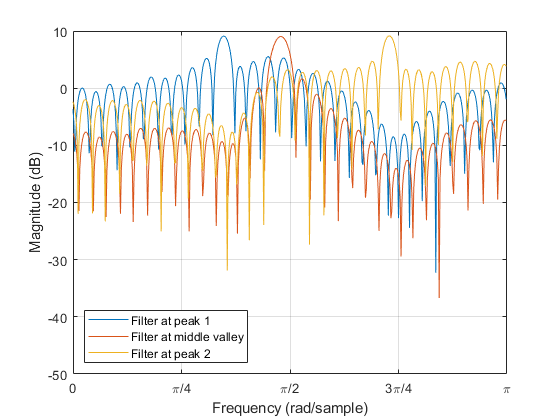

M = 64;
f1 = 1.1/(2*pi); % Correspond to the first peak
f2 = 1.5/(2*pi); % Middle valley
f3 = 2.3/(2*pi); % Second peak

% Compute the optimal filters
h1 = optfilter(x, M, f1);
h2 = optfilter(x, M, f2);
h3 = optfilter(x, M, f3);

% Compute the transfer function
[H1, w] = freqz(h1, 1);
[H2, ~] = freqz(h2, 1);
[H3, ~] = freqz(h3, 1);

plot(w, pow2db(abs(H1)), w, pow2db(abs(H2)), w, pow2db(abs(H3)));
set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude (dB)')
legend({'Filter at peak 1', 'Filter at middle valley', 'Filter at peak 2'}, 'Location', 'southwest')
grid on;
xlim([0, pi]);
ylim([-50, 10])

Note how the blue and red peak filters goes to zero at the other peak.

## ADSI Problem 4.22: Minimum variance and spectral resolution  

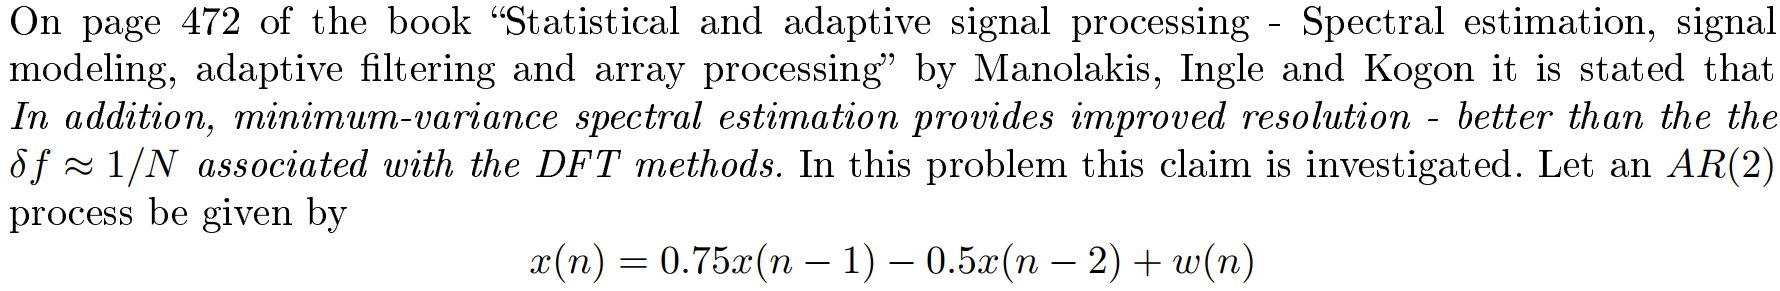

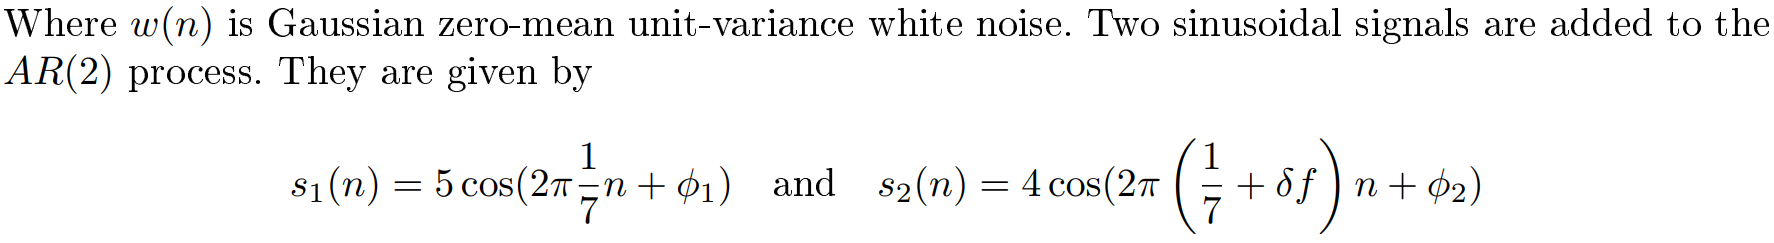

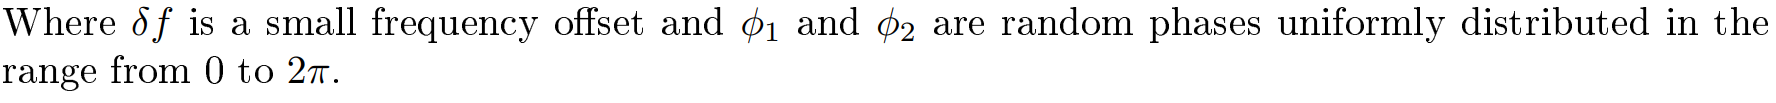

### 1) Create a realisation of the signal

### 2) Plot the spectrum of the process using minimum variance and the periodogram

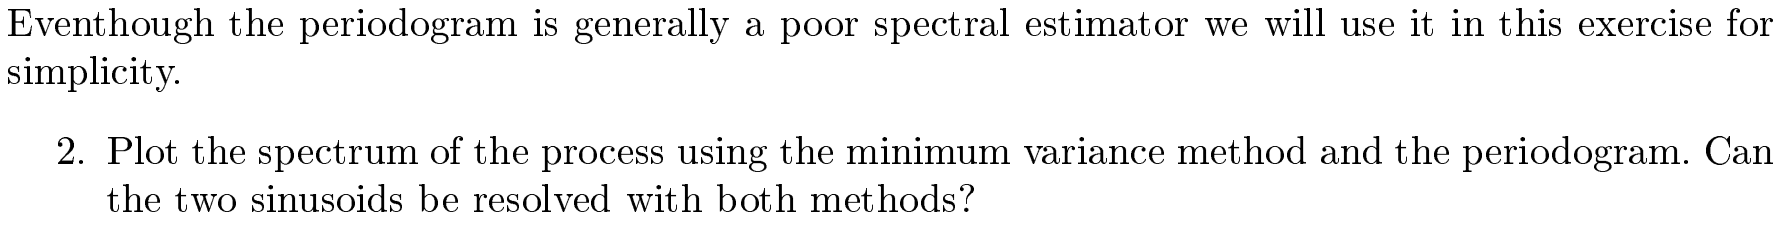

### 3) Verify if the book's claim is justified

## [✔] Exam 2012, Problem 2: Construct an AR(2) model using a signal from a random process

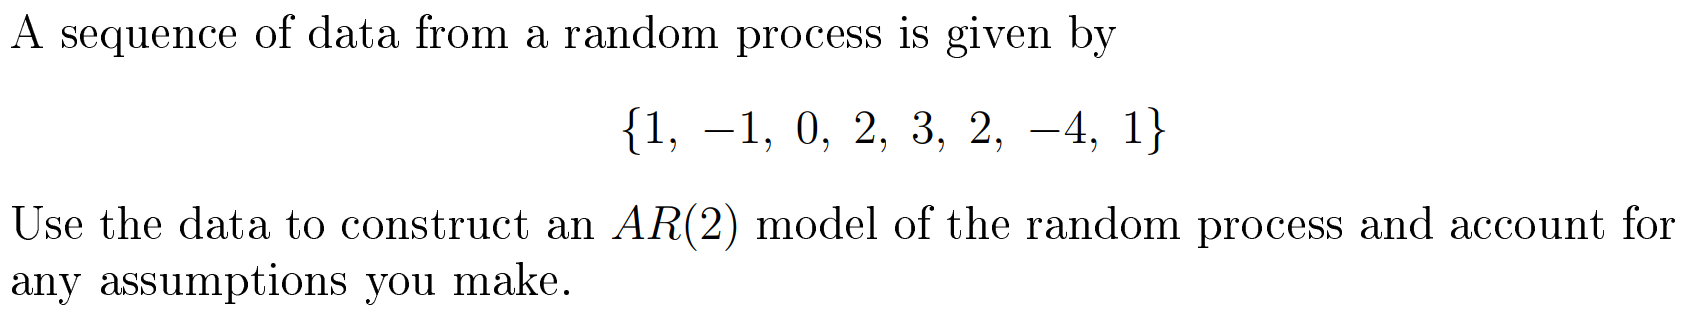

We assume that the given sequence is the output of a process whose input was white Gaussian noise with zero mean and unit variance:

        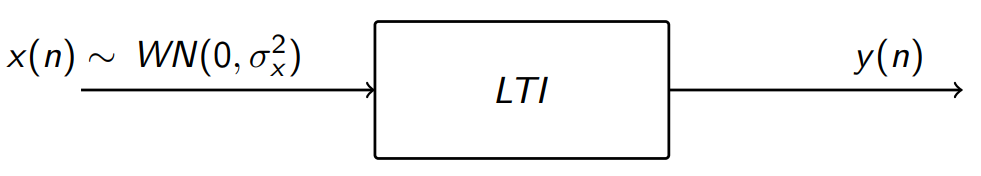

Given the input is white noise with zero mean $x\left(n\right)~\mathrm{WN}\left(0,\sigma_x^2 \right)$, the autocorrelation of an AR(q) model is given by Eq. 13.141:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model. Given an output signal $y\left(n\right)$, we can compute the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

For a second-order $p=2$ AR model, we get two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form:

        
$$\left\lbrack \begin{array}{cc}
r_{\textrm{yy}} \left(0\right) & r_{\textrm{yy}} \left(1\right)\\
r_{\textrm{yy}} \left(1\right) & r_{\textrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\textrm{yy}} \left(1\right)\\
r_{\textrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


Solving it will give us the AR(2) model coefficients $\left\lbrace a_1 ,a_2 \right\rbrace$.

This is implemented in the arfit() function:

y = [1, -1, 0, 2, 3, 2, -4, 1];
[a, ~] = arfit(y, 2)

a =     0.0340
    0.2232


The coefficients for the AR(2) model is; $a_1 =0\ldotp 0340$ and $a_2 =0\ldotp 2232$.

        
$$y\left(n\right)=-\left\lbrack 0\ldotp 0340y\left(n-1\right)+0\ldotp 2232y\left(n-2\right)\right\rbrack +b_0 x\left(n\right)$$


We can plot the signal and the estimated AR(2) signal:

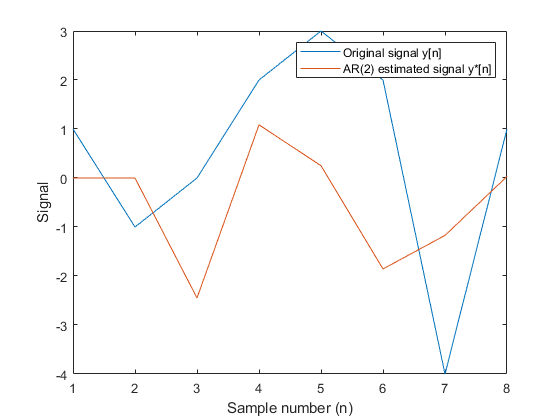

N = 8;

% Generate the input
x = randn(N, 1)'; % Random noise with zero mean and unit variance.
b0 = 1;

% Estimate the output signal using the AR(2) model
y_hat = zeros(N, 1);
n = 3:N; % Trick to make it work in MATLAB
y_hat(n) = -(a(1)*y(n-1) + a(2)*y(n-2)) + b0*x(n);

% Plot the two 
n = 1:N;
plot(n, y(n), n, y_hat(n))
legend('Original signal y[n]', 'AR(2) estimated signal y*[n]');
xlabel('Sample number (n)')
ylabel('Signal')

## Functions

function r=acrs(x, L)
    % Computes the ACRS r[m] for 0<= m <= L
    % r=acrs(x-mean(x),L) yields the ACVS
    N=length(x);
    x1=zeros(N+L-1,1);
    x2=x1;
    x1(1:N,1)=x;
    for m=1:L
        x2=zeros(N+L-1,1);
        x2(m:N+m-1,1)=x;
        r(m)=x1'*x2;
    end
    r=r(:)/N;
end

function I=psdper(x, K)
    % Compute periodogram I(ω) using the FFT.
    % K-point FFT >= N
    N=length(x);
    X=fft(x,K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function r=acrsfft(x, L)
    % Computate the autocorrelation sequence using the FFT.
    % r=acrsfft(x-mean(x),L) yields the ACVS
    N=length(x);
    Q=nextpow2(N+L);
    X=fft(x,2^Q);
    r0=real(ifft(X.*conj(X)));
    r=r0(1:L)/N;
end

function I=psdmodper(x, K)
    % Compute the modified periodogram PSD estimate.
    % K-point FFT >= N
    N=length(x);
    w=hann(N); % choose window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    X=fft(x(:).*w(:),K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function S=psdbt(x, L, K)
    % Computate the Blackman–Tukey PSD estimate.
    % Blackman–Tukey PSD estimator of S(2*pi*k/K)
    if size(x,1) < size(x,2)
        x = x';
    end
    N=length(x);
    w=hann(N); % Data window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    x=x.*w; % Data windowing
    r=acrsfft(x,L);
    wc=parzenwin(2*L-1); % Lag window
    rw=r.*wc(L:2*L-1); % Lag windowing
    g=zeros(K,1);
    g(1:L)=rw;
    g(K-L+2:K)=flipud(rw(2:L));
    G=fft(g,K); % f even => F real
    S=2*real(G(1:K/2)); 
    S(1)=S(2);
end

function S=psdwelch(x, L, K)
    % Compute the Welch PSD estimate.
    % Welch PSD estimator of S(2*pi*k/K)
    M=fix((length(x)-L/2)/(L/2)) % 50% overlap
    time=(1:L)';
    I=zeros(K,1);
    w=hanning(L); % Choose window
    w=w/(norm(w)/sqrt(L)); % sum wˆ2[k]=L
    for m=1:M
    %xw=w.*detrend(x(time)); % detrenting
    xw=w.*x(time); % data windowing
    X=fft(xw,K);
    I=I+X.*conj(X);
    time=time+L/2;
    end
    I=I/(M*L); S=2*I(1:K/2); S(1)=S(2);
end

function [a,v] = arfit(x,p)
    % fit AR(p) model from data
    % x: data
    % p: model order
    % a: a coefficients
    % v: variance
    if isrow(x)
        x = x'; % Convert to a column vector
    end
    
    % Compute the autocorrelation
    [r_xx, lags] = xcorr(x, p, 'biased');
    
    % Select elements r_xx[0] to r_xx[p-1]
    R_elems = r_xx(p+1:2*p);
    
    % Create the Toeplitz matrix
    R = toeplitz(R_elems);
    
    % Select elements r_xx[1] to r_xx[p]
    r = r_xx(p+2:2*p+1);
    
    % Solve systems of linear equations using mldivide function
    a = mldivide(R, -r);
    
    % Compute the variance
    v = r_xx(p+1) + a'*r;
end

function [S, w] = ar2psd(a, v, N)
% AR2PSD Compute the Power Spectral Density from AR(p) coefficients
%   [S, w] = ar2psd(a, v, N)
% a: AR(p) coefficients
% v: the variance
% N: number of points in the range [1, pi]
% S: the estimated power spectrum
% w: frequencies
    w = linspace(0, 1, N) * pi;
    
    % Compute the transfer function
    % Used Eq. (13.133) in the book
    H = ones(N, 1);
    for k=1:numel(a)
        H = H + a(k)*exp(-1j * w' * k);
    end
    H = 1./H;
    
    % Finally compute the PSD
    S = v * H.*conj(H);
end

function [psd, f] = psdmv(x, M, kF)
% Estimate PSD using Capon's Minimum Variance method
% x: input signal
% M: autocorrelation matrix size
% kF:frequency resolution multiplier
    if nargin < 3
        kF = 4;
    end
    if nargin < 2
        M = 64;
    end
    [rx, ~] = xcorr(x, M-1, 'biased');
    Rx=toeplitz(rx(M:end));% Autocorrelation matrix
    RxInv=inv(Rx);
    Nf = kF*M; % frequency resolution, Nf >= M
    f=0.5/Nf*(0:Nf-1); % freq spectrum
    psd=zeros(M,1); % pre-alloc
    t=(0:M-1)';
    for q=1:Nf
        Ef=exp(1i*2*pi*f(q)*t);
        psd(q)=M/(Ef'*RxInv*Ef);
    end
    f = 2*pi*f;
end

function h = optfilter(x, M, f)
% Compute the optimum filter for estimating a given frequency
% Computes Eq. (14.4.10) in the Minimum Variance material
% x: input signal
% M: autocorrelation matrix size (default: 64)
% f: the given frequency
    if nargin < 2
        M = 64;
    end
    [rx,~]=xcorr(x, M-1, 'biased');
    Rx=toeplitz(rx(M:end));
    invRx=inv(Rx);
    Ef = zeros(M, 1);
    for t=1:M
        % Compute E(f) vector
        Ef(t)=exp(1i*2*pi*f*(t-1));
    end
    h = (sqrt(M)*invRx*Ef) / (Ef'*invRx*Ef);
end